# Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

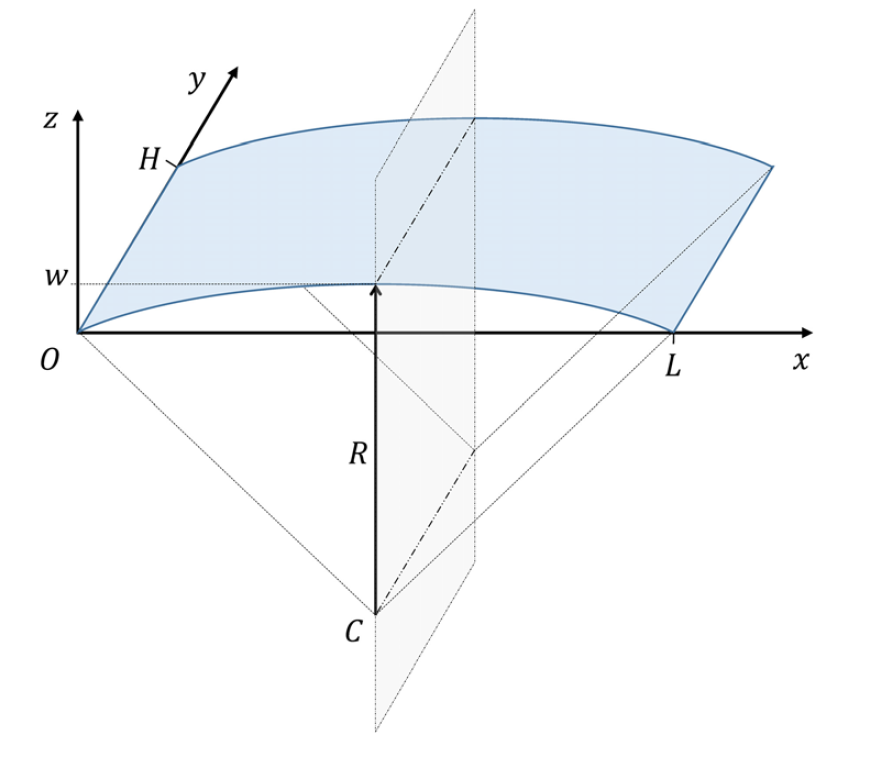

**System parameters**

clear all
clc
nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)
epsilon = 0.1; % converge at order 5

## generate model

Building FE model


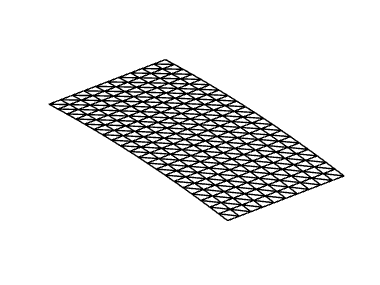

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  显示 所有属性

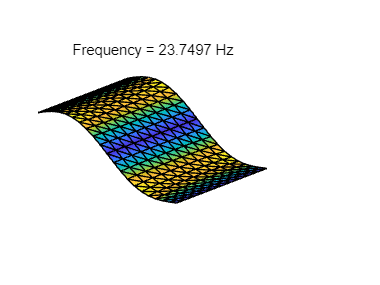

ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [400×3 double]
     Vertices: [1200×3 double]

  显示 所有属性

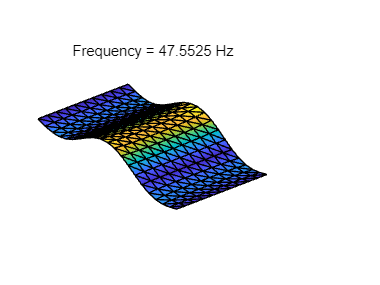

Using Rayleigh damping
Assembling external force vector
outnode
   171
outnode
    61
Getting nonlinearity coefficients
Assembling Tensors
Saving Tensors
Total time spent on model assembly = 00:00:11


[M,C,K,fnl,f_0,outdof] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',100,'Nmax',100,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

Bext     = zeros(n,2); Bext(outdof(1),1)=1; Bext(outdof(2),2)=1; 
% epsilon  = 0.1;
set(DS,'D',Bext,'epsilon',epsilon);

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 100 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.102524e-03
modal damping ratio for 4 mode is 2.141338e-03
modal damping ratio for 5 mode is 2.369557e-03
modal damping ratio for 6 mode is 2.577829e-03
modal damping ratio for 7 mode is 2.839286e-03
modal damping ratio for 8 mode is 3.021625e-03
modal damping ratio for 9 mode is 3.198610e-03
modal damping ratio for 10 mode is 3.514516e-03
modal damping ratio for 11 mode is 3.909708e-03
modal damping ratio for 12 mode is 4.443252e-03
modal damping ratio for 13 mode is 4.804011e-03
modal damping ratio for 14 mode is 4.921314e-03
modal damping ratio for 15 mode is 5.018352e-03
modal damping ratio for 16 mode is 5.346229e-03
modal damping rat

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
% set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2,3,4]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     0     0
     0     0     2     1
     1     1     1     0
     0     2     2     0
     2     0     1     1
     3     1     0     0
     0     0     3     2
     1     1     2     1
     2     2     1     0
     4     0     0     1
     0     2     3     1
     1     3     2     0
     2     0     2     2
     3     1     1     1
     4     2     0     0
     0     0     4     3
     0     4     3     0
     1     1     3     2
     2     2     2     1
     3     3     1     0
     4     0     1     2
     5     1     0     1
     0     2     4     2
     1     3     3     1
     2     0     3     3
     2     4     2     0
     3     1     2     2
     4     2     1     1
     5     3     0     0
     6     0     0     2
     0     0     5     4
     0     4     4     1
     1     1     4     3
     1     5     3     0
     2     2     3     2
     3     3     2     1
     4     0    

order = 3;
set(S.Options, 'reltol', 0.5,'IRtol',0.05,'notation', 'multiindex','contribNonAuto',true)
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.60E+01 MB
Manifold computation time at order 3 = 00:00:01
Estimated memory usage at order  3 = 2.10E+01 MB


set(DS.Options, 'outDOF', outdof);

auData = construct_autoData(DS, masterModes, R_0);   % use linear_spectral result 


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

choose frequency range around the first natural frequency

% set(S.FRCOptions,'coordinates','polar','initialSolver','forward');
% set(S.contOptions, 'h_min', 1e-2,'h_max',2,'PtMX',300);
% omega0 = imag(S.E.spectrum(1));
% omegaRange = omega0*[0.92 1.07];
% mFreq = [1 2];

extract forced response curve

% p0 = [omegaRange(1) epsilon]';
% z0 = 1e-3*[1 1 1 1]';
% S.SSM_isol2ep('isol-3',masterModes,order,mFreq,'freq',omegaRange,outdof,{p0,z0});

% % increase order
% order = 5;
% sol = ep_read_solution('','isol-3.ep',1);
% set(S.FRCOptions,'initialSolver','fsolve');
% S.SSM_isol2ep('isol-5',masterModes,order,mFreq,'freq',omegaRange,outdof,{sol.p,sol.x});


## Cutoff

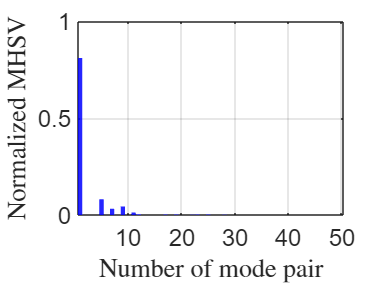

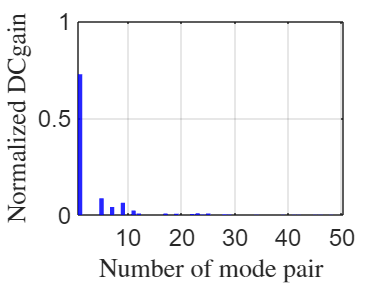

MHSV sum of the first 2 pair
    0.8104
DCgain sum of the first 2 pair
    0.7254


res = Cutof_LQR_closed_loop_MT2_comp(DS,50);

## Initial Condition

% om = 2*pi/2;
% nsteps = 200;
% z0     = zeros(2*n,1);
% DSstatic = DynamicalSystem();
% set(DSstatic,'M',M,'C',1000*C,'K',K,'fnl',fnl);
% set(DSstatic.Options,'HarmonicForce',false);
% fmidspan = zeros(n,1);
% fmidspan(outdof(1)) = 4000;
% Fmidspan = @(t) fmidspan;
% set(DSstatic,'fext',Fmidspan);
% [ts, xs, xf] = time_integration_transient(DSstatic,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','Newmark','outdof',outdof,'init',z0);
% figure;
% plot(ts,xs(:,1))
% z0 = xf;

% load("z0.mat","z0")
% load("load400.mat","z0")
% z0 = z0.z0;
% z0 = z0';

 
% tf     = 0.3; nsteps = 900;
% tspan0  = linspace(0,tf,nsteps);
% cont   = struct();
% % cont.Q    = 1e7.*blkdiag(eye(n,n),zeros(n,n));
% cont.Q    = 2e4*eye(2*n,2*n);
% cont.Rhat = 0.25*eye(2);
% % cont.Rhat = 10*eye(2);
% cont.Mhat = 1e1*eye(2*n); 


## Control


% % 
% 
% % om = 2*pi/tf;
% % set(DS,'u',[]);
% % [tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
% %     1, 'nSteps', nsteps,...
% %     'integrationMethod','Newmark','outdof',outdof,'init',z0);
% 
% % traj_closed1 = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W_0,masterModes,1:4,cont);
% traj_closed1 = LQR_closed_loop(DS,z0,'nonlinear',tspan0,auData,W_0,masterModes,[1:4,9:10,13:18,17:18,21:22],cont);
% % full dynamic
% om = 2*pi/tf;
% ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t,'linear','extrap'));
% set(DS,'u',ufun);
% [tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','Newmark','outdof',outdof,'init',z0);
% 
% figure; hold on
% plot(traj_closed1.time, traj_closed1.zt(1,:),'b--','DisplayName','SSM-closed loop');
% load("xfullwo.mat","xfullwo")
% load("tfullwo.mat","tfullwo")
% plot(tfullwo, xfullwo(:,1),'k-','DisplayName','Full-without-control');
% plot(tfullwc, xfullwc(:,1),'r-.','DisplayName','Full-with-control');
% xlabel('$t$','Interpreter',"latex")
% zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% ylabel(zk,'Interpreter','latex');
% title('4D Reduction')
% set(gca,'FontSize',18);
% grid on, axis tight
% legend('show','Interpreter','latex'); legend boxoff
% set(gca,'FontSize',18); grid on, axis tight
% 
% figure; hold on;
% plot(traj_closed1.time,real(traj_closed1.ut(1,:)),'b--','DisplayName', '$u_1$');
% plot(traj_closed1.time,real(traj_closed1.ut(2,:)),'k-.','DisplayName', '$u_2$');
% xlabel('$t$','Interpreter',"latex")
% ylabel('$u(t)$','Interpreter','latex')
% legend('show','Interpreter','latex'); legend boxoff
% set(gca,'FontSize',18); grid on, axis tight


## 3Segs

load("load400.mat","z0");
xf = z0';
z0 = xf';


cont   = struct();
cont.Q    = 3e4*eye(2*n,2*n);
cont.Rhat = 0.5*eye(2);
cont.Mhat = 2*eye(2*n); 

% cont   = struct();
% cont.Q    = 4e4*eye(2*n,2*n);
% cont.Rhat = 0.2*eye(2);
% cont.Mhat = 1*eye(2*n); 


nsteps = 300;

% 3segs
t0 = 0; t1 = 0.05;
tspan3 = linspace(t0,t1,nsteps);
traj3  = LQR_closed_loop(DS,z0,'linear',tspan3,auData,W_0,masterModes,[1:2,9:10,13:14,17:18],cont);

pl
  -0.1008 + 0.0002i
  -0.1008 - 0.0002i
   0.0168 - 0.0000i
   0.0168 + 0.0000i
p0
  -0.1008 + 0.0002i
  -0.1008 - 0.0002i
   0.0168 - 0.0000i
   0.0168 + 0.0000i
历时 0.113565 秒。
历时 0.069956 秒。
Time for backward simulation of Riccati ODE is 7.244280e-02
历时 0.554964 秒。
Time for backward simulation of compensated ODE is 5.564504e-01
历时 0.450122 秒。
Time for forward simulation of ODEs for modal coordinates is 4.545613e-01



ufun3 = @(t) transpose(interp1(traj3.time,traj3.ut',t,'linear','extrap'));
set(DS,'u',ufun3);
[tfull3, xfull3,x3f,xt3] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99993
Iteration 1, Residual norm = 0.16561
Iteration 2, Residual norm = 6.0826e-05
Iteration 3, Residual norm = 3.6474e-09
time integration completed: 0.33333%
Iteration 0, Residual norm = 0.99975
Iteration 1, Residual norm = 0.16829
Iteration 2, Residual norm = 0.00014008
Iteration 3, Residual norm = 2.6014e-09
time integration completed: 0.66667%
Iteration 0, Residual norm = 0.99973
Iteration 1, Residual norm = 0.090295
Iteration 2, Residual norm = 0.00033745
Iteration 3, Residual norm = 1.8347e-08
time integration completed: 1%
Iteration 0, Residual norm = 0.99982
Iteration 1, Residual norm = 0.065021
Iteration 2, Residual norm = 3.6388e-05
time integration completed: 1.3333%
Iteration 0, Residual norm = 0.99968
Iteration 1, Residual norm = 0.055854
Iteration 2, Residual norm = 0.00037403
Iteration 3, Residual norm = 1.3128e-08
time integration completed: 1.6667%
Iteration 0, Residual norm = 0.99942
Iteration 1, Residual norm = 0.034922
Iteration 2, Re


xf = x3f';

% cont   = struct();
% cont.Q    = 2e4*eye(2*n,2*n);
% cont.Rhat = 0.25*eye(2);
% cont.Mhat = 1e1*eye(2*n); 

t2 = 0.1;
tspan4 = linspace(t1,t2,nsteps);
% traj4  = LQR_closed_loop(DS,xf,'linear',tspan4,auData,W_0,masterModes,[1:4,9:10,13:18,17:18,21:22],cont);
traj4  = LQR_closed_loop(DS,xf,'linear',tspan4,auData,W_0,masterModes,[1:2,9:10,13:14,17:18],cont);

pl
  -0.0097 - 0.0436i
  -0.0097 + 0.0436i
   0.0159 + 0.0241i
   0.0159 - 0.0241i
p0
  -0.0097 - 0.0436i
  -0.0097 + 0.0436i
   0.0159 + 0.0241i
   0.0159 - 0.0241i
历时 0.095227 秒。
历时 0.041013 秒。
Time for backward simulation of Riccati ODE is 4.253340e-02
历时 0.522892 秒。
Time for backward simulation of compensated ODE is 5.241806e-01
历时 0.367133 秒。
Time for forward simulation of ODEs for modal coordinates is 3.714351e-01


% traj4  = LQR_closed_loop(DS,xf,'linear',tspan4,auData,W_0,masterModes,1:4,cont);
ufun4 = @(t) transpose(interp1(traj4.time,traj4.ut',t,'linear','extrap'));
set(DS,'u',ufun4);
[tfull4, xfull4,x4f,xt4] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t1);

Iteration 0, Residual norm = 0.70717
Iteration 1, Residual norm = 6.5308e-05
Iteration 2, Residual norm = 1.4348e-13
time integration completed: 50.1667%
Iteration 0, Residual norm = 0.69308
Iteration 1, Residual norm = 6.4144e-05
Iteration 2, Residual norm = 1.4211e-13
time integration completed: 50.3333%
Iteration 0, Residual norm = 0.70496
Iteration 1, Residual norm = 5.1475e-05
Iteration 2, Residual norm = 1.4167e-13
time integration completed: 50.5%
Iteration 0, Residual norm = 0.64468
Iteration 1, Residual norm = 4.8003e-05
time integration completed: 50.6667%
Iteration 0, Residual norm = 0.65885
Iteration 1, Residual norm = 3.5658e-05
time integration completed: 50.8333%
Iteration 0, Residual norm = 0.5969
Iteration 1, Residual norm = 3.6738e-05
time integration completed: 51%
Iteration 0, Residual norm = 0.62196
Iteration 1, Residual norm = 4.4838e-05
time integration completed: 51.1667%
Iteration 0, Residual norm = 0.60148
Iteration 1, Residual norm = 5.1763e-05
Iteration 2, R


xf = x4f';

t3 = 0.2;
tspan5 = linspace(t2,t3,nsteps);
% traj5  = LQR_closed_loop(DS,xf,'linear',tspan5,auData,W_0,masterModes,[1:4,9:10,13:18,17:18,21:22],cont);
traj5  = LQR_closed_loop(DS,xf,'linear',tspan5,auData,W_0,masterModes,[1:2,9:10,13:14,17:18],cont);

pl
   0.0124 - 0.0021i
   0.0124 + 0.0021i
  -0.0270 - 0.0146i
  -0.0270 + 0.0146i
p0
   0.0124 - 0.0021i
   0.0124 + 0.0021i
  -0.0270 - 0.0146i
  -0.0270 + 0.0146i
历时 0.163332 秒。
历时 0.047249 秒。
Time for backward simulation of Riccati ODE is 4.874970e-02
历时 0.729340 秒。
Time for backward simulation of compensated ODE is 7.317495e-01
历时 0.621118 秒。
Time for forward simulation of ODEs for modal coordinates is 6.262963e-01


% traj5  = LQR_closed_loop(DS,xf,'linear',tspan5,auData,W_0,masterModes,1:4,cont);
ufun5 = @(t) transpose(interp1(traj5.time,traj5.ut',t,'linear','extrap'));
set(DS,'u',ufun5);
[tfull5, xfull5,x5f,xt5] = time_integration_transient(DS,2*pi/(t3-t2),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t2);

Iteration 0, Residual norm = 0.89009
Iteration 1, Residual norm = 0.00028925
Iteration 2, Residual norm = 1.0521e-11
time integration completed: 50.1667%
Iteration 0, Residual norm = 0.92206
Iteration 1, Residual norm = 0.00015116
Iteration 2, Residual norm = 3.1623e-13
time integration completed: 50.3333%
Iteration 0, Residual norm = 0.8566
Iteration 1, Residual norm = 0.00021788
Iteration 2, Residual norm = 1.4381e-12
time integration completed: 50.5%
Iteration 0, Residual norm = 0.85847
Iteration 1, Residual norm = 0.00025178
Iteration 2, Residual norm = 2.7599e-12
time integration completed: 50.6667%
Iteration 0, Residual norm = 0.84909
Iteration 1, Residual norm = 0.00029947
Iteration 2, Residual norm = 9.7877e-13
time integration completed: 50.8333%
Iteration 0, Residual norm = 0.82533
Iteration 1, Residual norm = 0.0003053
Iteration 2, Residual norm = 3.6464e-13
time integration completed: 51%
Iteration 0, Residual norm = 0.8374
Iteration 1, Residual norm = 0.00025543
Iteration 


% xf = x5f';
% 
% t4 = 0.4;
% tspan6 = linspace(t3,t4,nsteps);
% traj6  = LQR_closed_loop(DS,xf,'linear',tspan6,auData,W_0,masterModes,1:4,cont);
% 
% ufun6 = @(t) transpose(interp1(traj6.time,traj6.ut',t,'linear','extrap'));
% set(DS,'u',ufun6);
% [tfull6, xfull6,x6f,xt6] = time_integration_transient(DS,2*pi/(t4-t3),'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t3);
% 

% load("traj3.mat","traj3")
% load("traj4.mat","traj4")
% load("traj5.mat","traj5")
% load("tfull3.mat","tfull3")
% load("xfull3.mat","xfull3")
% load("tfull4.mat","tfull4")
% load("xfull4.mat","xfull4")
% load("tfull5.mat","tfull5")
% load("xfull5.mat","xfull5")

figure; hold on
plot(traj3.time, traj3.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
load("xfullwo.mat","xfullwo")
load("tfullwo.mat","tfullwo")
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfull3, xfull3(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);
% plot(traj3.time,traj3.zt_auto(1,:),"g--",'DisplayName','W(p)')
plot(traj4.time, traj4.zt(1,:),'b--','LineWidth',2);
plot(tfull4, xfull4(:,1),'r-.','LineWidth',2);
% plot(traj4.time,traj4.zt_auto(1,:),"g--")

plot(traj5.time, traj5.zt(1,:),'b--','LineWidth',2);
plot(tfull5, xfull5(:,1),'r-.','LineWidth',2);
% plot(traj5.time,traj5.zt_auto(1,:),"g--")
% 
% plot(traj6.time, traj6.zt(1,:),'b--');
% plot(tfull6, xfull6(:,1),'r-.');
% plot(traj6.time,traj6.zt_auto(1,:),"g--")

legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w_\mathrm{A}$ [m]');
ylabel(zk,'Interpreter','latex');
title('(4N, 8L)','Interpreter','latex')
set(gca,'FontSize',18);
grid on, axis tight
xlim([0,0.2])


figure;
plot(traj3.time,traj3.ut(1,:),'b-','DisplayName', '$u_A$','LineWidth',2); hold on
plot(traj3.time,traj3.ut(2,:),'k-','DisplayName', '$u_B$','LineWidth',2); hold on
plot(traj4.time,traj4.ut(1,:),'b-','LineWidth',2); hold on
plot(traj4.time,traj4.ut(2,:),'k-','LineWidth',2); hold on
plot(traj5.time,traj5.ut(1,:),'b-','LineWidth',2); hold on
plot(traj5.time,traj5.ut(2,:),'k-','LineWidth',2); hold on
% plot(traj6.time,traj6.ut(1,:),'b--'); hold on
% plot(traj6.time,traj6.ut(2,:),'k--'); hold on
legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex')
set(gca,'FontSize',20); grid on, axis tight
box off


% figure; hold on
% % tt = [traj3.time, traj4.time];
% % zt = [traj3.zt, traj4.zt];
% % zauto = [traj3.zt_auto, traj4.zt_auto];
% % ep_Vq = zt - zauto;
% 
% plot(traj3.time, traj3.zt_auto(2,:),'b--','DisplayName','$W(p)$','LineWidth',2);
% plot(traj3.time, traj3.zt(2,:)-traj3.zt_auto(2,:),'k-.','DisplayName','$\epsilon Vq$','LineWidth',2);
% 
% plot(traj4.time, traj4.zt_auto(2,:),'b--','DisplayName','none','LineWidth',2);
% plot(traj4.time, traj4.zt(2,:)-traj3.zt_auto(2,:),'k-.','LineWidth',2);
% 
% legend('show','Interpreter',"latex",'Location','southeast'); legend boxoff
% xlabel('$t$ ','Interpreter',"latex")
% % zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% % ylabel(zk,'Interpreter','latex');
% title('(2N, 2L)', 'Interpreter','latex')
% set(gca,'FontSize',20);
% grid on
% % axis tight
% legend boxon
% print(gcf, 'Shell_z(t)_Factorization.png', '-dpng','-r300');


% load("traj3.mat","traj3")
% load("traj4.mat","traj4")
% load("traj5.mat","traj5")
% 
% figure; hold on
% % tt = [traj3.time, traj4.time];
% % zt = [traj3.zt, traj4.zt];
% % zauto = [traj3.zt_auto, traj4.zt_auto];
% % ep_Vq = zt - zauto;
% 
% plot(traj3.time, traj3.zt_auto(1,:),'b--','DisplayName','$W(p)$','LineWidth',2);
% plot(traj3.time, traj3.zt(1,:)-traj3.zt_auto(1,:),'k-.','DisplayName','$\epsilon Vq$','LineWidth',2);
% 
% plot(traj4.time, traj4.zt_auto(1,:),'b--','LineWidth',2);
% plot(traj4.time, traj4.zt(1,:)-traj4.zt_auto(1,:),'k-.','LineWidth',2);
% 
% plot(traj5.time, traj5.zt_auto(1,:),'b--','LineWidth',2);
% plot(traj5.time, traj5.zt(1,:)-traj5.zt_auto(1,:),'k-.','LineWidth',2);
% 
% legend('show','Interpreter',"latex",'Location','best'); legend boxoff
% xlabel('$t$ ','Interpreter',"latex")
% % zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% % ylabel(zk,'Interpreter','latex');
% title('(4N, 10L)', 'Interpreter','latex')
% set(gca,'FontSize',20);
% grid on
% % axis tight
% legend boxon
% print(gcf, 'ShellIRs_z(t)_Factorization.png', '-dpng','-r300');

## Draw

% vt  =  [xt3; xt4; xt5];
% n   = size(vt,1);
% % Draw(nDiscretization,vt)
% hfig = figure;
% hold on;
% for i = 1:n
%     clf;
%     resref = Draw(nDiscretization,vt(1,:));
%     res    = Draw(nDiscretization,vt(i,:));
%     saveas(res, ['frame' num2str(i, '%03d') '.png']);
%     drawnow
%     close(gcf)
% end